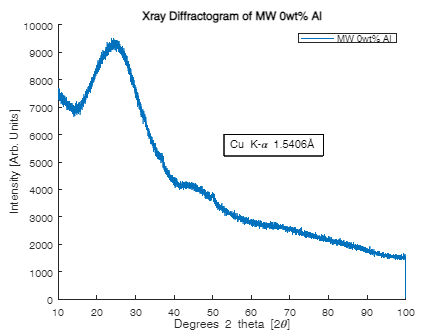

%clearing crap
clear all
clf

%file to import (Intensity vs 2theta)
file="C:\\Users\Jack\MATLAB Drive\PhD Work\XRD Plotter_240524\MW0_raw_280524.csv";

%importing file
data = readtable(file);

%subsetting x & y data
x = data{:,1};
y = data{:,2};

%performing plot
plot(x,y)

%beautifying curve
ax = gca;
ax.XAxisLocation = "origin";
ax.YAxisLocation = "origin";
box off;

%Naming sample
sample = "MW 0wt% Al";

%labelling gprah
xlabel("Degrees 2 theta [2\theta]")
ylabel("Intensity [Arb. Units]")
title(strcat("Xray Diffractogram of ", sample))
legend(sample, "Location", "NorthEast")
%annotation
text = {strcat('Cu K-\alpha 1.5406',[char(197)])};
%text = {'This is a text box'; 'with multiple lines'; 'and more information.'};
%[x-loc, y-loc, width, height]
annotation("textbox", [0.5, 0.1, 0.5, 0.5], "string", text, "FitBoxToText", "on")